# Cviceni 10

## Radkove vyplnovani

Priklad ze slidu 3

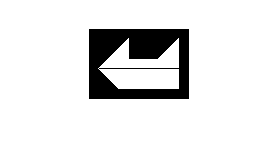

clc

img = zeros(70,100);
body = [60,30; 40,10; 10,40; 30,40; 30,70; 10,90; 60,90;60,30];
pocet_bodu = size(body,1)-1; 

% smernice jednotlivzch usecek
% (y2 - y1) / (x2-x1)
smernice = zeros(1,pocet_bodu);
for i = 1: pocet_bodu
    smernice(i) = (body(i+1,2)-body(i,2))/(body(i+1,1)-body(i,1));
end

% Hrany, ktere se pocitaji
hrany = [];
for i = 1: pocet_bodu
    if(smernice(i) < Inf && smernice(i) > -Inf)
        hrany = [hrany; body(i,:), body(i+1,:)];
    end
end

pocet_hran = size(hrany,1);
%display(hrany);

% nalezeni vsech hranic na y
for j = min(body(:,1)) : max(body(:,1))
    pruseciky_x = [];
    for i = 1 : pocet_hran
        t = (j - hrany(i,1))/(hrany(i,3)-hrany(i,1));
        
        if (t>=0 && t <=1)  %kontrola zda lezi na usecce
            x = hrany(i,2) + t*(hrany(i,4)-hrany(i,2));
            pruseciky_x = [pruseciky_x, x];
        end
    end
    %display(j);
    %display(pruseciky_x);
    pruseciky_x = sort(pruseciky_x);
   for k = 1 : 2 : size(pruseciky_x,2)-1
       for l = round(pruseciky_x(k)) : round(pruseciky_x(k+1))
           img(j,l) = 1;
       end        
   end
end
figure, imshow(img);

## Ukol 1

Upravte predchozi kod pro vyplnovani trojuhelniku. Obecny trojuhelnik se rozdeli na dva rezem prochazejicim bodem jehoz y souradnice lezi mezi y souradnicema zbylych dvou. Oba tyto trojuhelniky lze pak posat jen 2 hranama (3. je vodorovna a tudiz ji vynechavame, viz predchozi algoritmus. Pro kazdy radek najdeme pruseciky s obema hranama a vyplnime oblast mezi nima.

## Srafovani

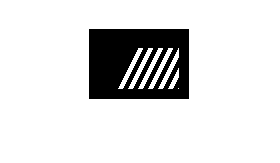

img = zeros(70,100);
body = [60,30; 20,50; 20,90; 60,90];

pocet_bodu = size(body,1)-1; 

smernice = zeros(1,pocet_bodu);
for i = 1: pocet_bodu
    smernice(i) = (body(i+1,2)-body(i,2))/(body(i+1,1)-body(i,1));
end

hrany = [];
for i = 1: pocet_bodu
    if(smernice(i) < Inf && smernice(i) > -Inf)
        hrany = [hrany; body(i,:), body(i+1,:)];
    end
end

pocet_hran = size(hrany,1);

delka_useku = 5;


for j = min(body(:,1)) : max(body(:,1))
    pruseciky_x = [];
    for i = 1 : pocet_hran
        t = (j - hrany(i,1))/(hrany(i,3)-hrany(i,1));
        
        if (t>=0 && t <=1)  
            x = hrany(i,2) + t*(hrany(i,4)-hrany(i,2));
            pruseciky_x = [pruseciky_x, x];
        end
    end
    
   pruseciky_x = sort(pruseciky_x);
   for k = 1 : 2 : size(pruseciky_x,2)-1
       plny = 1;
       aktualni_delka = delka_useku;
       for l = round(pruseciky_x(k)) : round(pruseciky_x(k+1))
          if(plny==1)
              img(j,l) = 1;
          end
          aktualni_delka = aktualni_delka -1;
          if(aktualni_delka ==0)
                if(plny == 1)
                    plny = 0;
                else
                plny = 1;
            end
            aktualni_delka = delka_useku;
          end
       end        
   end
end
figure, imshow(img);

## Srafovani 2

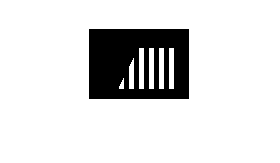

m = 70;
n=100;
img = zeros(m,n);
body = [60,30; 20,50; 20,90; 60,90];

% srafy vztazene k x = 1
x = 1;
% x = min(body(:,2));

delka_useku = 5;
aktualni_delka = delka_useku;
plny = 1;
srafy = zeros(1,n);
for i = x : n
    if(plny == 1)
        srafy(i) = 1;
    end
    aktualni_delka = aktualni_delka -1;
    if(aktualni_delka ==0)
        if(plny == 1)
             plny = 0;
        else
             plny = 1;
        end
         aktualni_delka = delka_useku;
    end
end

pocet_bodu = size(body,1)-1; 

smernice = zeros(1,pocet_bodu);
for i = 1: pocet_bodu
    smernice(i) = (body(i+1,2)-body(i,2))/(body(i+1,1)-body(i,1));
end

hrany = [];
for i = 1: pocet_bodu
    if(smernice(i) < Inf && smernice(i) > -Inf)
        hrany = [hrany; body(i,:), body(i+1,:)];
    end
end

pocet_hran = size(hrany,1);




for j = min(body(:,1)) : max(body(:,1))
    pruseciky_x = [];
    for i = 1 : pocet_hran
        t = (j - hrany(i,1))/(hrany(i,3)-hrany(i,1));
        
        if (t>=0 && t <=1)  
            x = hrany(i,2) + t*(hrany(i,4)-hrany(i,2));
            pruseciky_x = [pruseciky_x, x];
        end
    end
    
   pruseciky_x = sort(pruseciky_x);
   for k = 1 : 2 : size(pruseciky_x,2)-1
       plny = 1;
       aktualni_delka = delka_useku;
       for l = round(pruseciky_x(k)) : round(pruseciky_x(k+1))
              img(j,l) = srafy(l);
       end        
   end
end
figure, imshow(img);

## Vyplneni oblasti obrazkem

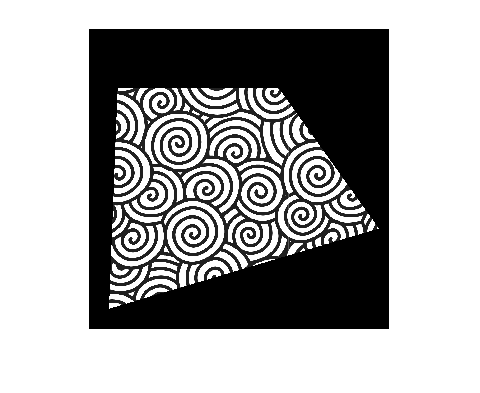

vzor = rgb2gray(imread("pattern_small.png"));
[mv, nv] = size(vzor);

img = uint8(zeros(300,300));
body = [50,30; 280,21; 200,290; 60,190];

pocet_bodu = size(body,1)-1; 

smernice = zeros(1,pocet_bodu);
for i = 1: pocet_bodu
    smernice(i) = (body(i+1,2)-body(i,2))/(body(i+1,1)-body(i,1));
end

hrany = [];
for i = 1: pocet_bodu
    if(smernice(i) < Inf && smernice(i) > -Inf)
        hrany = [hrany; body(i,:), body(i+1,:)];
    end
end

pocet_hran = size(hrany,1);

for j = min(body(:,1)) : max(body(:,1))
    pruseciky_x = [];
    for i = 1 : pocet_hran
        t = (j - hrany(i,1))/(hrany(i,3)-hrany(i,1));
        
        if (t>=0 && t <=1)  
            x = hrany(i,2) + t*(hrany(i,4)-hrany(i,2));
            pruseciky_x = [pruseciky_x, x];
        end
    end
    
   pruseciky_x = sort(pruseciky_x);
   for k = 1 : 2 : size(pruseciky_x,2)-1
       for l = round(pruseciky_x(k)) : round(pruseciky_x(k+1))
            img(j,l) = vzor(mod(j,mv)+1,mod(l,nv)+1);
       end        
   end
end
figure, imshow(img);

## Hranice v rastru

funkce imfill

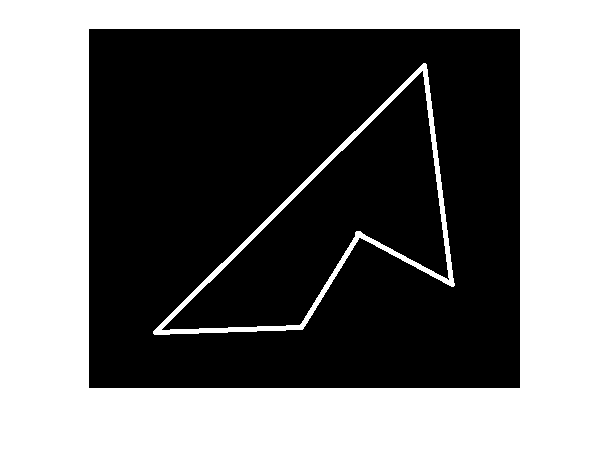

I = logical(imread('oblast.png'));
imshow(I);

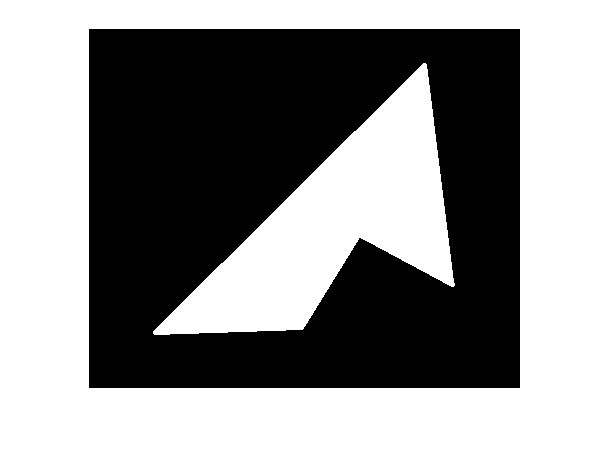


BW2= imfill(I,[200,250],8);
figure, imshow(BW2);

## Ukol 2

Naprogramujte funkci pro vyplneni oblasti pomoci seed fill. Argumenty funkce: oblast (1 tvori hranici,0 nevyplnenou oblast), seminko (dvourozmerny vektor) a cislo urcujici, zda je oblast 4 nebo 8 sousedna. Bude tedy pracovat stejne jako funkce imfill Vyzkousejte rozdíl ve vyplneni obrazku "oblast_ukol.png", seminko [60,60] pri volbe 4 a 8 sousednosti.

% Vyroba obrazku oblast_ukol.png
% I = zeros(100);
% I(20:40,20) = 1;
% I(40,20:40) = 1;
% I(40:80,40) = 1;
% I(80,40:80) = 1;
% I(39:80,80) = 1;
% I(39,41:80) = 1;
% I(20:39,41)=1;
% I(20,20:41) = 1;
% 
% %I(60,60)=1;
% 
% imshow(I);
% 
% imwrite(I,'oblast_ukol.png');